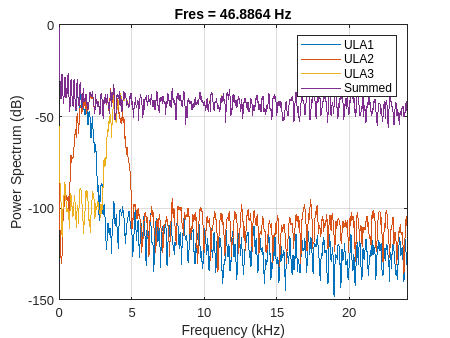

clear
close all
clc
data = load('log.DAS.20240503105143.txt'); % output af DAS
fs = 48e3;
t = 0:1/fs:(length(data)-1)/fs;
%plot(t,data)

output_ula1 = data(:,1);
output_ula2 = data(:,2);
output_ula3 = data(:,3);
output = data(:,4);

%plot(t,inputData)

% plot(t,output_ula1)
% hold on
% plot(t,output_ula2)
% plot(t,output_ula3)
% xlim([0.01 0.012])
% grid minor
% legend('input', 'output')
% title('Raw')
% hold off

% delayLength = 21; % HVORFOR 21??
% plot(t(1:end-delayLength),inputData(1:end-delayLength))
% hold on
% plot(t(1:end-delayLength),output_ula1(delayLength+1:end))
% xlim([0.0 0.002])
% grid minor
% legend('input', 'output')
% title('Offset')
% hold off

%spectrogram(inputData,fs)
%pwelch(inputData)
%pspectrum(inputData,fs)

pspectrum(output_ula1,fs)
hold on
pspectrum(output_ula2,fs)
pspectrum(output_ula3,fs)
pspectrum(output,fs)
legend('ULA1', 'ULA2', 'ULA3', 'Summed')
hold off

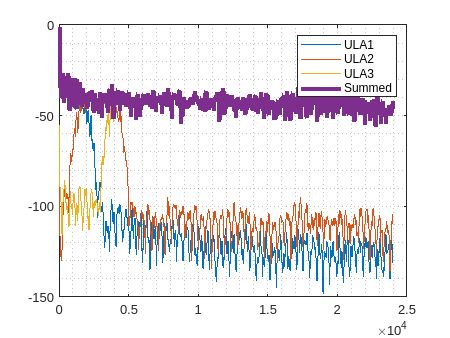


[p_ula1, f_ula1] = pspectrum(output_ula1,fs);
[p_ula2, f_ula2] = pspectrum(output_ula2,fs);
[p_ula3, f_ula3] = pspectrum(output_ula3,fs);
[p_sum, f_sum] = pspectrum(output,fs);


plot(f_ula1,10*log10(p_ula1))
hold on
plot(f_ula2,10*log10(p_ula2))
plot(f_ula3,10*log10(p_ula3))
plot(f_sum,10*log10(p_sum), 'LineWidth', 3)
legend('ULA1', 'ULA2', 'ULA3', 'Summed')
grid minor
hold off


%[pxx,f] = pwelch(output,[],[],[],fs);
% [pxx,f] = pspectrum(output,fs);
% plot(f,10*log10(pxx))
